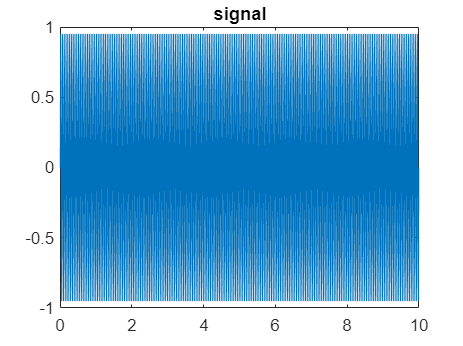

clear all;
close all;

f0 = 20;
fe = 100;
Te = 1/fe;
t = 0:Te:10; 
A = 1;

x = A*sin(2*pi*f0*t);

% Représentation du signal
figure;
plot(t, x);
title('signal');

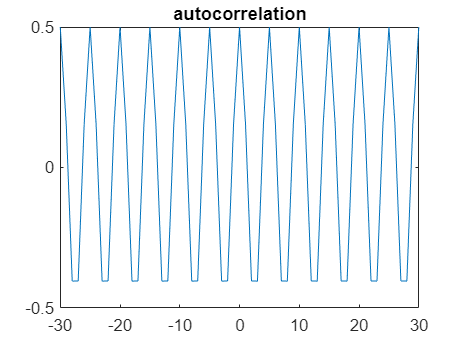


% Calcul de l'autocorrélation du signal
maxlag = 30;
r = xcorr(x, maxlag,'unbiased');
lag = -maxlag:maxlag;
figure;
plot(lag,r);
title('autocorrelation');

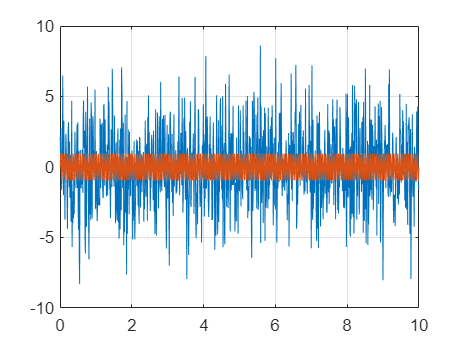


% Calcul du bruit gaussien
b=randn(size(x));
b = b-mean(b);
b = sqrt(7)*b/std(b);

% Signal bruité
xb = x+b;

figure;
plot(t, xb, t, x);
grid;

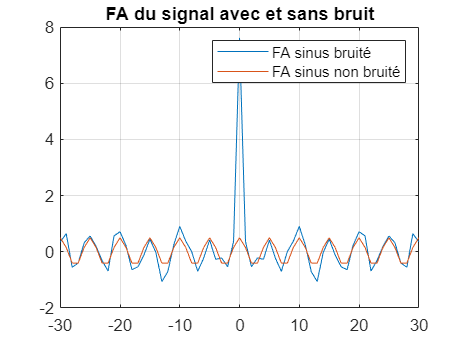


rb = xcorr(xb, maxlag, 'unbiased');

% Représentation des fonctions d'autocorrélation des sinus bruité et non
% bruité
figure;
plot(lag, rb, lag, r);
grid;
title('FA du signal avec et sans bruit');
legend('FA sinus bruité', 'FA sinus non bruité');